# Model Health Parameters

以下の変数が RUL に関係しているかどうかの確認。論文には

At present, the N-CMAPSS dataset contains eight sets of data from 128 units and seven different failure modes affecting the flow (F) and/or efficiency (E) of all the rotating sub-components. Table 2 provides an overview of flight classes and failure modes for each of the sets of data provided 

とある通り、DS 番号によって入れ込まれている故障モードは様々なようなので、それぞれで挙動が異なることが想定される。

- fan_eff_mod: Fan efficiency modifier (-)

- fan_flow_mod: Fan flow modifier (-)

- LPC_eff_mod: LPC efficiency modifier (-)

- LPC_flow_mod: LPC flow modifier (-)

- HPC_eff_mod: HPC efficiency modifier (-)

- HPC_flow_mod: HPC flow modifier (-)

- HPT_eff_mod: HPT efficiency modifier (-)

- HPT_flow_mod: HPT flow modifier (-)

- LPT_eff_mod: LPT efficiency modifier (-)

- LPT_flow_mod: LPT flow modifier (-)

clear

fileID = ["DS01-005", "DS02-006", "DS03-012", "DS04", "DS05", ...
    "DS06", "DS07", "DS08a-009", "DS08c-008"];


Unit 毎に平均値をプロットしてみるか。X 軸は Y (RUL) で。

eff_mod_list = ["fan_eff_mod";"fan_flow_mod";"LPC_eff_mod";"LPC_flow_mod";...
    "HPC_eff_mod";"HPC_flow_mod";"HPT_eff_mod";"HPT_flow_mod";
    "LPT_eff_mod";"LPT_flow_mod"];
meaneff_mod_list = "mean" + eff_mod_list;

% other_list = ["T48";"SmLPC";"SmHPC"];
other_list = ["T48";"SmFan";"SmLPC";"SmHPC"];
meanother_list = "mean" + other_list;


failmodes = {7;[7,9,10];[7,9,10];[1,2];[5,6];[3,4,5,6];[9,10];1:10;1:10}

failmodes = 9×1 の cell 配列
    {[                   7]}
    {[              7 9 10]}
    {[              7 9 10]}
    {[                 1 2]}
    {[                 5 6]}
    {[             3 4 5 6]}
    {[                9 10]}
    {[1 2 3 4 5 6 7 8 9 10]}
    {[1 2 3 4 5 6 7 8 9 10]}


% failmodes = {7;[7,9,10];[7,9,10];[1,2];[5,6];[3,4,5,6];[9,10];1:10;1:10}
% に該当する変数だけが値を持つことを確認
% failID(2) の冒頭３つは 9,10 が 0. 変動なし。
% それぞれの cycle では変動しない模様（マニュアル確認）
% for ii=1:length(fileID)
trainData = [];
testData = [];
for ii=1:length(fileID)
    load("train_" + fileID(ii) + "Unwrap_OtherParam2.mat","dTrainUnwrap");

    for jj=1:height(dTrainUnwrap)
        dUnit = dTrainUnwrap.data{jj};

        if height(dUnit) == 100 && unique(dUnit.Fc) == 1 % xxxx
            continue
        end

        dUnit.DS = repmat(fileID(ii),height(dUnit),1);
        dUnit.Unit = repmat(dTrainUnwrap.unit(jj),height(dUnit),1);

        if unique(dUnit.DS == 'DS02-006') && ...
                (dUnit.Unit(1) == 2 || dUnit.Unit(1) == 5 || dUnit.Unit(1) == 10)
            dUnit.DS = repmat(fileID(1),height(dUnit),1);
        end

        tmp = dUnit{:,meaneff_mod_list};
        tmp = movmean(tmp,5);

        for kk=1:size(tmp,2)
            p = polyfit(1:10,tmp(1:10,kk),1);
            tmp(:,kk) = tmp(:,kk) - p(2);
        end

        [~,scores,~] = pca(tmp);

        dUnit{:,meaneff_mod_list} = tmp;
        dUnit.score1 = scores(:,1)-scores(1,1);


        mvscore = movmean(dUnit.score1,1);

        idxh0init = find(dUnit.hs == 0,1);
        idxh0fint = find(dUnit.cycle == 40,1);
        x = dUnit.cycle(idxh0init-3:idxh0fint);
        y = mvscore(idxh0init-3:idxh0fint);
        %         idx = dUnit.hs == 0 & dUnit.cycle <= 40;
        %         x = dUnit.cycle(idx);
        %         y = mvscore(idx);

        x0 = [0.002,1.5];
        opts = optimoptions('fmincon','TypicalX',x0,'Display',"none");
        p = fmincon(@(a)myfun(a,[x-x(1),y-y(1)]),x0,[],[],[],[],[0.0001,1.4],[0.003,1.6],[],opts);
        dUnit.p1 = p(1)*ones(height(dUnit),1);
        dUnit.p2 = p(2)*ones(height(dUnit),1);

        dTrainUnwrap.data{jj} =  dUnit;
        dTrainUnwrap.p1(jj) = p(1);
        dTrainUnwrap.p2(jj) = p(2);
        %         dUnit = dUnit(1:40,:);

        trainData = [trainData; dUnit];


    end
    save("train_" + fileID(ii) + "Unwrap_PowerCoeff.mat","dTrainUnwrap");

    load("test_" + fileID(ii) + "Unwrap_OtherParam2.mat","dTestUnwrap");

    for jj=1:height(dTestUnwrap)
        dUnit = dTestUnwrap.data{jj};
        dUnit.DS = repmat(fileID(ii),height(dUnit),1);
        dUnit.Unit = repmat(dTestUnwrap.unit(jj),height(dUnit),1);

        tmp = dUnit{:,meaneff_mod_list};

        tmp = movmean(tmp,5);

        for kk=1:size(tmp,2)
            p = polyfit(1:10,tmp(1:10,kk),1);
            p(2);
            tmp(:,kk) = tmp(:,kk) - p(2);
        end


        [~,scores,~] = pca(tmp);

        dUnit{:,meaneff_mod_list} = tmp;
        dUnit.score1 = scores(:,1)-scores(1,1);

        mvscore = movmean(dUnit.score1,1);
        idxh0init = find(dUnit.hs == 0,1);
        idxh0fint = find(dUnit.cycle == 40,1);
        x = dUnit.cycle(idxh0init-3:idxh0fint);
        y = mvscore(idxh0init-3:idxh0fint);


        x0 = [0.002,1.5];
        opts = optimoptions('fmincon','TypicalX',x0,'Display',"none");
        p = fmincon(@(a)myfun(a,[x-x(1),y-y(1)]),x0,[],[],[],[],[0.0001,1.4],[0.003,1.6],[],opts);
        dUnit.p1 = p(1)*ones(height(dUnit),1);
        dUnit.p2 = p(2)*ones(height(dUnit),1);

        dTestUnwrap.data{jj} =  dUnit;
        dTestUnwrap.p1(jj) = p(1);
        dTestUnwrap.p2(jj) = p(2);
        testData = [testData; dUnit];

    end
    save("test_" + fileID(ii) + "Unwrap_PowerCoeff.mat","dTestUnwrap");
end


% colors = [colororder; colororder];
%
% % for ii=1:length(fileID)
% for ii=8
%     load("train_" + fileID(ii) + "Unwrap_PowerCoeff.mat","dTrainUnwrap");
%
%     figure(1)
%     legends = [];
%     for jj=1:height(dTrainUnwrap)
%         dUnit = dTrainUnwrap.data{jj};
%
%         legends = [legends; fileID(ii) + "  " ...
%             +  dTrainUnwrap.unit(jj) + " " ...
%             +  dTrainUnwrap.data{jj}.Y(1) + " "];
%
%
%         idxh0init = find(dUnit.hs == 0,1);
%         idxh0fint = find(dUnit.cycle == 40,1);
%         x = dUnit.cycle(idxh0init:idxh0fint);
%         y = dUnit.score1(idxh0init:idxh0fint);
%
%         %         idx = dUnit.hs == 0 & dUnit.cycle <= 40;
%         %         x = dUnit.cycle(idx);
%         %         y = dUnit.score1(idx);
%
%         a = dTrainUnwrap.p1(jj);
%         b = dTrainUnwrap.p2(jj);
%         xx = x-x(1);
%         yy = y-y(1);
%         yfit = 1-exp((a*xx).^b);
%         plot(xx+x(1),yfit+y(1),'Color',colors(jj,:),'LineWidth',2);
%         hold on
%         plot(xx+x(1),yy+y(1),'o-','Color',colors(jj,:),'LineWidth',1);
%         legends = [legends; ""];
%     end
%     hold off
%     legend(legends,'Location',"best")
%
% end
%

%
% for ii=8
%
%     load("test_" + fileID(ii) + "Unwrap_PowerCoeff.mat","dTestUnwrap");
%
%     legends = [];
%     figure(2)
%     for jj=1:height(dTestUnwrap)
%
%         dUnit = dTestUnwrap.data{jj};
%
%         legends = [legends; fileID(ii) + "  " ...
%             +  dTestUnwrap.unit(jj)];
%
%         idxh0init = find(dUnit.hs == 0,1);
%         idxh0fint = find(dUnit.cycle == 40,1);
%         x = dUnit.cycle(idxh0init:idxh0fint);
%         y = dUnit.score1(idxh0init:idxh0fint);
%
%         %         idx = dUnit.hs == 0 & dUnit.cycle <= 40;
%         %         x = dUnit.cycle(idx);
%         %         y = dUnit.score1(idx);
%
%         a = dTestUnwrap.p1(jj);
%         b = dTestUnwrap.p2(jj);
%         xx = x-x(1);
%         yy = y-y(1);
%         yfit = 1-exp((a*xx).^b);
%         plot(xx+x(1),yfit+y(1),'Color',colors(jj,:),'LineWidth',2);
%         hold on
%         plot(xx+x(1),yy+y(1),'o-','Color',colors(jj,:),'LineWidth',1);
%         legends = [legends; ""];
%     end
%     hold off
%     legend(legends)
%     legend(legends,'Location',"best")
% end
%





[~,score,~] = pca([trainData{:,meaneff_mod_list};testData{:,meaneff_mod_list}]);
trainData.score11 = score(1:height(trainData),1);
testData.score11 = score(height(trainData)+1:end,1);


% trainData2 = trainData(:,["cycle","Y","score1","score2","score3","Fc","hs","DS","p1","p2"]);
trainData2 = trainData(:,["cycle","Y",meaneff_mod_list',meanother_list',"Fc","hs","DS","p1","p2","score1"]);
% trainData2 = trainData(:,["Y",meaneff_mod_list',meanother_list',"Fc","hs","DS","p1","p2"]);
% trainData2 = trainData(:,["cycle","Y",meaneff_mod_list',meanother_list',"Fc","hs","DS"]);

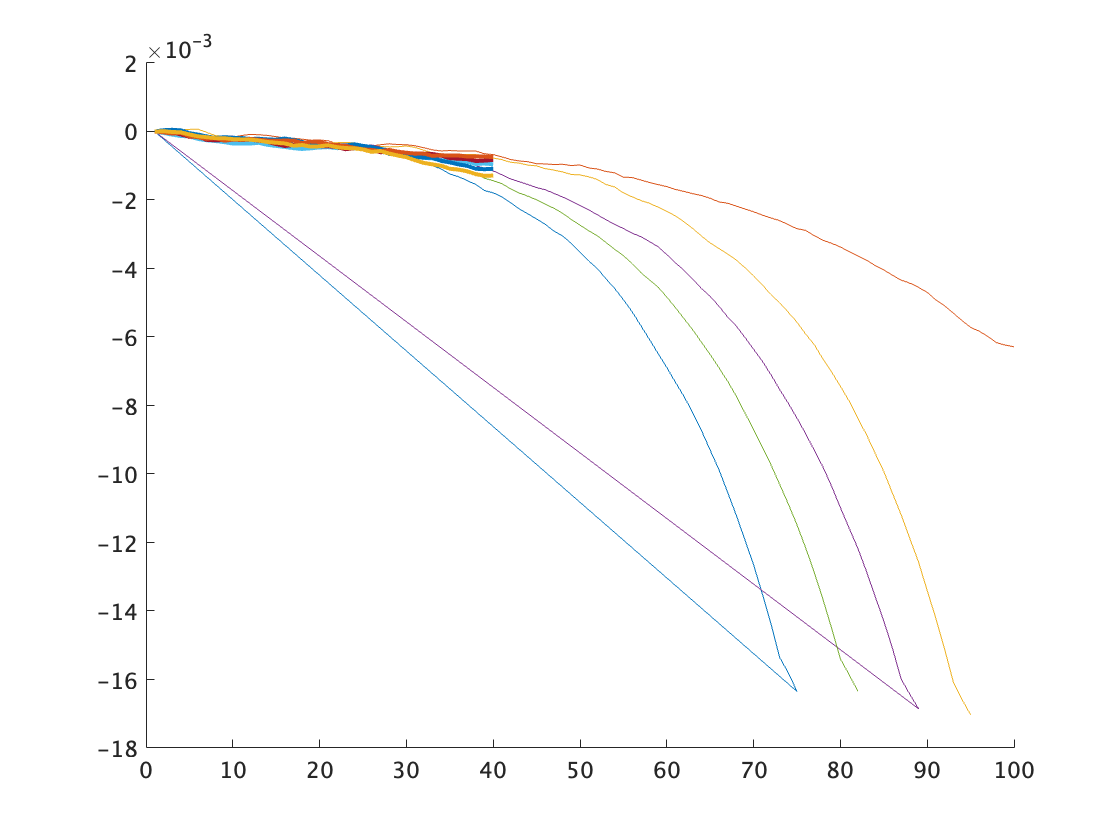

fileID = ["DS01-005", "DS02-006", "DS03-012", "DS04", "DS05", ...
    "DS06", "DS07", "DS08a-009", "DS08c-008"];

for ii=1
    file = fileID(ii);
    tmpTR = trainData(trainData.DS == string(file),:);
    tmpTE = testData(testData.DS == string(file),:);

    for jj = 1:max(tmpTR.Unit)
        idxUnit = tmpTR.Unit == jj;
        tmp2 = tmpTR(idxUnit,:);
        plot(tmp2.cycle,tmp2.score1);
        hold on
    end

    for jj = 1:max(tmpTE.Unit)
        idxUnit = tmpTE.Unit == jj;
        tmp2 = tmpTE(idxUnit,:);
        plot(tmp2.cycle,tmp2.score1,'LineWidth',2);
        hold on
    end
    hold off

end

ベイズオプト

- [`Method`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#bvcj_tw-1-Method) — 使用可能な方式は `'Bag'` または `'LSBoost'` です。

- [`NumLearningCycles`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#bvcj_tw-1-NumLearningCycles) — `fitrensemble` は、既定では範囲 `[10,500]` の対数スケールで、正の整数を探索します。

- [`LearnRate`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#mw_0b7f0d4a-2aae-4c52-a876-a6cb06c15ba4) — `fitrensemble` は、既定では範囲 `[1e-3,1]` の対数スケールで、正の実数を探索します。

- [`MinLeafSize`](https://www.mathworks.com/help/releases/R2021a/stats/fitrtree.html#bt6cr84-MinLeafSize) — `fitrensemble` は、範囲 `[1,max(2,floor(NumObservations/2))]` の対数スケールで整数を探索します。

- [`MaxNumSplits`](https://www.mathworks.com/help/releases/R2021a/stats/fitrtree.html#bt6cr84-MaxNumSplits) — `fitrensemble` は、範囲 `[1,max(2,NumObservations-1)]` の対数スケールで整数を探索します。

- [`NumVariablesToSample`](https://www.mathworks.com/help/releases/R2021a/stats/fitrtree.html#bt6cr84-NumVariablesToSample) — `fitrensemble` は、範囲 `[1,max(2,NumPredictors)]` の整数値を探索します。


rng(0)
% opt.UseParallel = true;
% opt.MaxObjectiveEvaluations = 30;
% t = templateTree('Surrogate','on');
% mdl = fitrensemble(trainData2,'Y','Learners',t, ...
%     'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',opt);

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      5.9987 |     0.83462 |      5.9987 |      5.9987 |      LSboost |           33 |     0.027547 |          516 |
|    2 | Accept |      7.4055 |      1.3148 |      5.9987 |      6.0745 |      LSboost |           53 |    0.0018978 |            2 |
|    3 | Best   |      4.1443 |      11.373 |      4.1443 |      4.1447 |      LSboost |          468 |     0.051433 |           32 |
|    4 | Best   |      4.0419 |       1.356 |      4.0419 |   

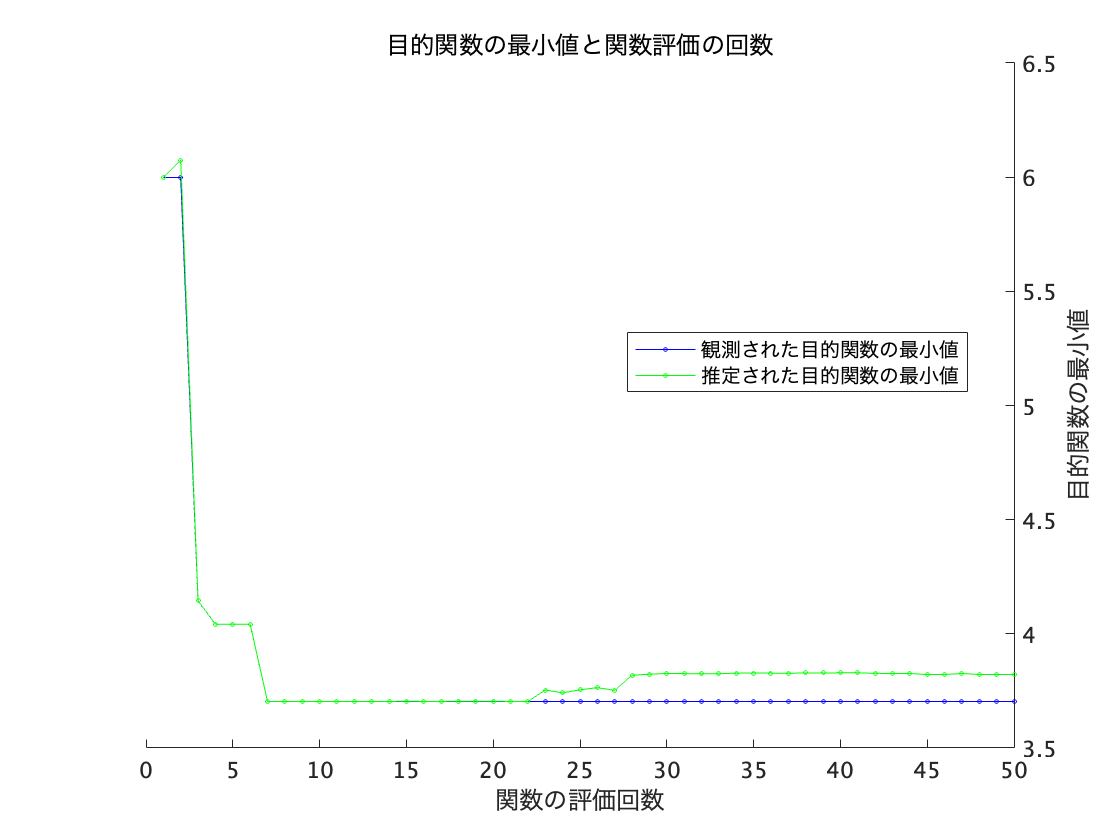


__________________________________________________________
最適化が完了しました。
MaxObjectiveEvaluations の 50 に達しました。
関数の評価回数の合計: 50
経過時間の合計: 270.8139 秒
目的関数の評価時間の合計: 241.7979

最適な観測実行可能点:
    Method    NumLearningCycles       LearnRate        MinLeafSize
    ______    _________________    ________________    ___________

     Bag             21            0.28689746832778        10     

観測された目的関数値 = 3.7037
推定される目的関数値 = 3.822
関数の評価時間 = 0.80014

最適な推定実行可能点 (モデルに基づく):
    Method    NumLearningCycles       LearnRate        MinLeafSize
    ______    _________________    ________________    ___________

     Bag             21            0.28689746832778        10     

推定される目的関数値 = 3.822
推定される関数評価時間 = 0.80021



rng(0)
NumObservations = height(trainData2);
NumPredictors = width(trainData2)-1;

Method = optimizableVariable('Method',["Bag","LSboost"],'Type','categorical');
NumLearningCycles = optimizableVariable('NumLearningCycles',[10,500],'Transform','log','Type',"integer");
LearnRate = optimizableVariable('LearnRate',[1e-3,1],'Transform','log');
MinLeafSize = optimizableVariable('MinLeafSize',[1,max(2,floor(NumObservations/2))],'Transform','log','Type',"integer");

vars = [Method,NumLearningCycles,LearnRate,MinLeafSize];

fun = @(vars) myBayesGroup(vars,trainData,trainData2);

results = bayesopt(fun,vars,'UseParallel',false,...
    'AcquisitionFunctionName',"expected-improvement-plus",...
    'MaxObjectiveEvaluations',50);

optvars = results.XAtMinEstimatedObjective;
mdl = myBayesOptModel(optvars,trainData2);

a = predictorImportance(mdl);
[~,idx] = sort(a,'descend');
mdl.PredictorNames(idx)'

ans = 21×1 の cell 配列
    {'score1'          }
    {'cycle'           }
    {'meanHPT_eff_mod' }
    {'p1'              }
    {'meanLPT_eff_mod' }
    {'meanSmLPC'       }
    {'meanLPT_flow_mod'}
    {'hs'              }
    {'DS'              }
    {'meanHPC_flow_mod'}
    {'p2'              }
    {'meanHPC_eff_mod' }
    {'meanHPT_flow_mod'}
    {'meanfan_eff_mod' }
    {'meanLPC_flow_mod'}
    {'meanfan_flow_mod'}
    {'meanSmHPC'       }
    {'Fc'              }
    {'meanT48'         }
    {'meanLPC_eff_mod' }
    {'meanSmFan'       }





predTrain = mdl.predict(trainData2);

norm(predTrain-trainData2.Y)

ans =      1.325295347060647e+02


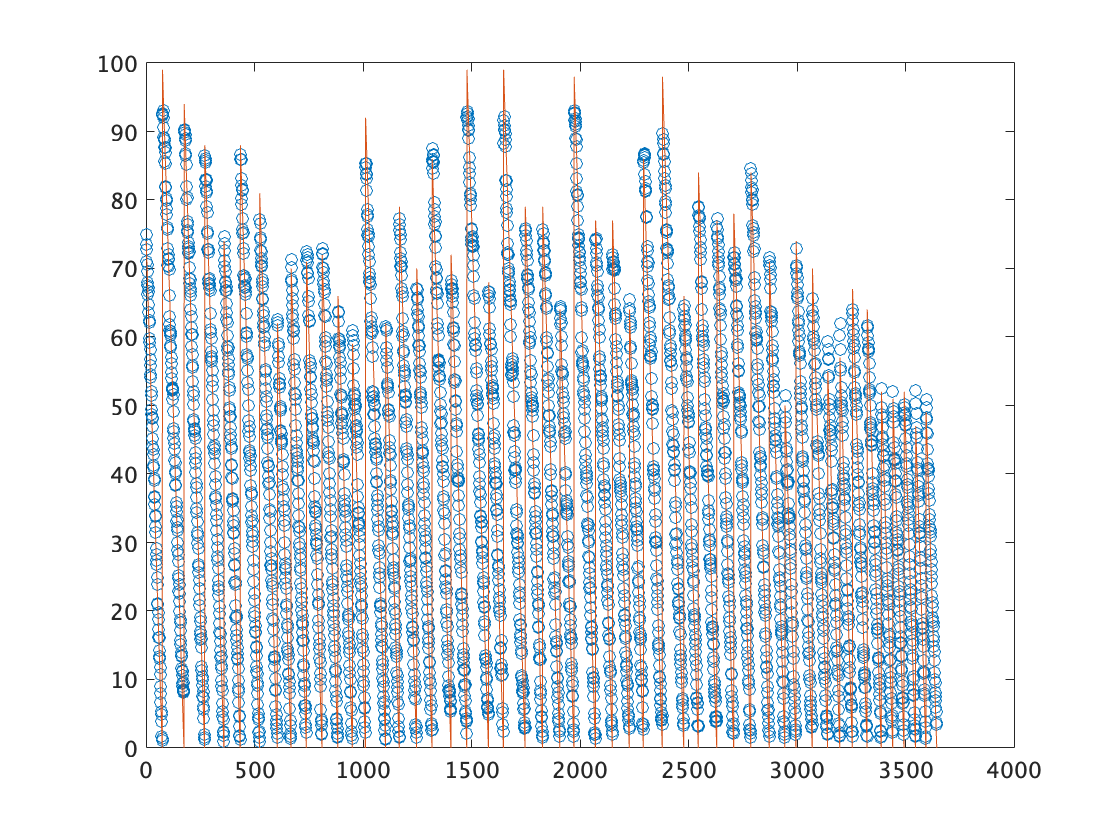


figure
plot(predTrain,'o');
hold on
plot(trainData2.Y,'-')
hold off

diffUnit = diff(trainData.Unit);
idx = find(abs(diffUnit)>0)+1;
idx = [1;idx;height(trainData)];

%  y = - x + C;
Clist = 99:-1:40;
error = zeros(size(Clist));
Cfix = zeros(size(idx,1)-1,1);
Ctrue = zeros(size(idx,1)-1,1);
for jj=1:size(idx,1)-1
    tmp = predTrain(idx(jj):idx(jj+1)-1);
    for ii=1:length(Clist)
        C = Clist(ii);
        yy = C - (0:length(tmp));
        error(ii) = norm(yy-tmp);
    end
    [~,minidx] = min(error);
    Cfix(jj) = Clist(minidx);
    Ctrue(jj) = trainData2.Y(idx(jj));
end
[Cfix, Ctrue]

ans =     76    74
    99    99
    94    94
    88    88
    76    74
    88    88
    81    81
    63    62
    70    70
    75    71


norm(Cfix-Ctrue)

ans =   12.449899597988733


testData2 = testData(:,["cycle",meaneff_mod_list',meanother_list',"Fc","hs","DS","p1","p2","score1"]);
% testData2 = testData(:,[meaneff_mod_list',meanother_list',"Fc","hs","DS","p1","p2"]);
% testData2 = testData(:,["cycle",meaneff_mod_list',meanother_list',"Fc","hs","DS"]);
predTest = mdl.predict(testData2);

predTest2 = reshape(predTest, 40, []);
x1 = 0:39;
%  y = - x + C;
Clist = 99:-1:40;
error = zeros(size(Clist));
Cfix = zeros(size(predTest2,2),1);
for jj=1:size(predTest2,2)
    for ii=1:length(Clist)
        C = Clist(ii);
        yy = C - x1;
        error(ii) = norm(yy-predTest2(:,jj));
    end
    [~,idx] = min(error);
    Cfix(jj) = Clist(idx);
end
Cfix

Cfix =     90
    91
    91
    93
    85
    63
    78
    73
    67
    75



unit = reshape(testData.Unit, 40, []);
filename = reshape(testData.DS, 40, []);

output = table(filename(1,:)',unit(1,:)',Cfix,'VariableNames',["filename","unit","Y"]);
writetable(output,'submission_ensemble_alldata_try.csv')

a = readtable('../submission_ensemble_alldata_model.csv');
sqrt((mean((a.Y(1:48)-Cfix).^2)))

ans =    6.617527232030607


[a.Y(1:48),Cfix,a.Y(1:48)-Cfix]

ans =     93    90     3
    89    91    -2
    88    91    -3
    79    93   -14
    81    85    -4
    58    63    -5
    75    78    -3
    66    73    -7
    65    67    -2
    83    75     8


function errors = myfun(x,data)

a = x(1);
b = x(2);


yfit = 1-exp((a*data(:,1)).^b);
% yfit = 1-a*exp(data(:,1).^b);
errors = norm(data(:,2)-yfit);

end
